# Data Processing Procedure (DPP)

**Objective: **Hydrogen Deflagration Time-Series Analysis.

## **Procedure Steps**

## **Data Acquisition and Import**

### Collect Raw Data

Record the pressure data from the deflagration test at a known sampling rate and store all relevant metadata (e.g., test conditions, sensor specifications).

### Import into MATLAB

Load the raw time-series data (e.g., using load or CSV import) and verify the correct time alignment, sampling frequency, and units.

### Outcome

A raw pressure signal and associated metadata are available in MATLAB.

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

## Import Signal Data

## Load "Raw" Signal

**Note: **Details on DAQ system setting are required, to check if any hardware filters has been used.

load('E2038.mat');  

## Exploratory Data Analysis (EDA)

### **Visual Inspection**

Plot the raw signal to identify the main deflagration event, noise, and anomalies. Check for sensor clipping or saturation.

### **Descriptive Statistics**

Compute basic statistics (mean, variance, outliers) and estimate the event time window.

**Released Mass of Hydrogen [g]** 

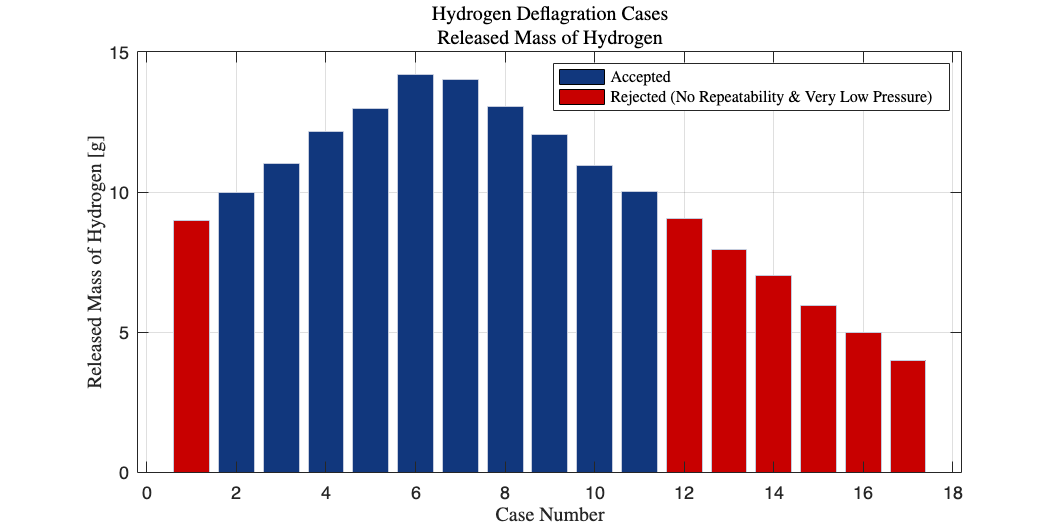

dataRMH = cases; % [g]
cases = 1:length(dataRMH);
% Define custom colors for boundary conditions
bar_colors = [AuxFcn_GS.LUBlue; AuxFcn_GS.darkred];
% Case Staus
Case_Staus = {'Accepted', 'Rejected (No Repeatability $\&$ Very Low Pressure)'};
% Create the bar plot with 'flat' FaceColor for per-bar coloring
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])
barPlot = bar(cases, dataRMH, 'FaceColor', 'flat', 'EdgeColor', AuxFcn_GS.LUBlue_Light);

% Set default color for all bars
defaultColor = bar_colors(1,:); % Ensure this is an RGB triplet
barPlot.CData = repmat(defaultColor, length(dataRMH), 1);

% Define indices of bars to change and their new color
indicesToChange = [1,12:1:17]; % Example indices
newColor = bar_colors(2,:); % Example: red; replace with desired RGB triplet

% Update colors for selected bars
barPlot.CData(indicesToChange, :) = repmat(newColor, numel(indicesToChange), 1);

AuxFcn_Figure_Settings('Case Number','Released Mass of Hydrogen [g]',''...
    ,{'Hydrogen Deflagration Cases','Released Mass of Hydrogen'},12)

% Add legend manually using "dummy" bars
hold on;
legend_handles = gobjects(length(Case_Staus),1);  % Create empty objects for legend
for i = 1:length(Case_Staus)
    legend_handles(i) = bar(nan, nan, 'FaceColor', bar_colors(i, :)); % Create dummy bars for legend
end
legend(legend_handles, Case_Staus, 'Location', 'northeast');

**Raw Pressure Reading [bar]**

dataPraw = p*1000; % [mbar]
% Compute mean, max, and min across each test (column-wise)
meanValues = mean(dataPraw, 1); % Mean for each test
maxValues = max(dataPraw, [], 1); % Max for each test
minValues = min(dataPraw, [], 1); % Min for each test
% Create a test number column (1 to 17)
testNumbers = (1:length(cases))';
% Convert to table format
dataSummary = table(testNumbers,dataRMH', meanValues', maxValues', minValues', ...
    'VariableNames', {'Test Number','Released Mass of Hydrogen [g]', 'Mean [mbar]', 'Max [mbar]', 'Min [mbar]'});
% Display the table
disp(dataSummary);

    Test Number    Released Mass of Hydrogen [g]    Mean [mbar]    Max [mbar]    Min [mbar]
    ___________    _____________________________    ___________    __________    __________

         1                      8.99                  -37.241       -18.688       -51.562  
         2                        10                  -30.283       -6.9375       -42.312  
         3                     11.03                  -30.234         85.75       -128.12  
         4                     12.16                  -16.319        96.438       -102.38  
         5                     12.99                  -56.073        33.938       -176.06  
         6                      14.2                  -8.8778        174.75       -135.94  
         7                     14.01                  -43.309         166.5       -196.69  
 

**Baseline/Offset Assessment**

Identify any baseline offset and decide on necessary baseline correction.

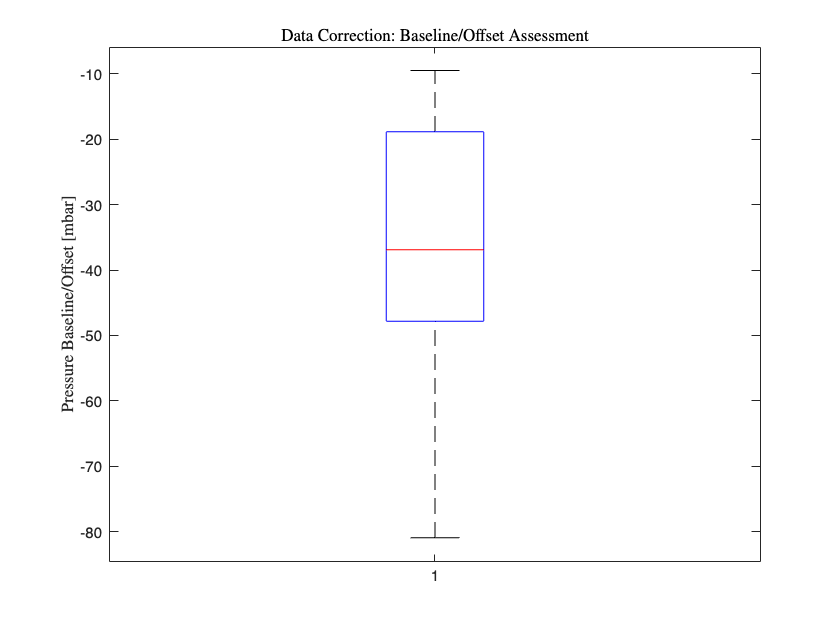

Fs = fs;             % Sampling frequency in Hz
t = (0:length(dataPraw)-1)'/Fs;
offset_Assessment = mean(p(1:100,:)*1000, 1);% [mbar]
figure;
boxplot(offset_Assessment);
ylabel('Pressure Baseline/Offset [mbar]')
box on
title('Data Correction: Baseline/Offset Assessment')

## Signal Preprocessing

Pressure reading corrected (offset/baseline removed)

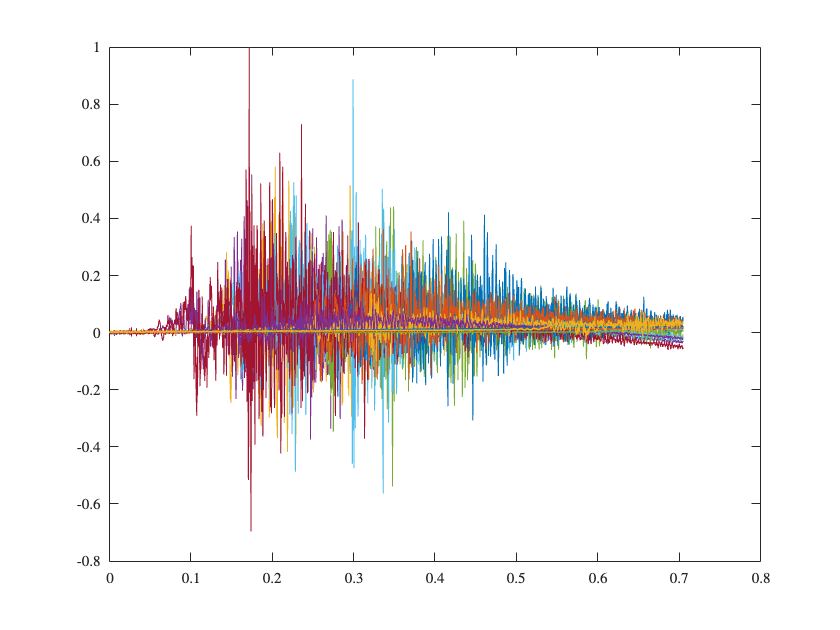

dataPoffsetCorrected = (p - mean(p(1:100,:), 1)) * 1000;% [mbar]
% dataPoffsetCorrected = detrend((p - mean(p(1:100,:), 1))) * 1000;% [mbar]
% dataPoffsetCorrected = p(:,1:17) - mean(p(1:100,1:17), 1);
globalMax = max(max(abs(dataPoffsetCorrected))); % Global max across tests
dataNormalised = dataPoffsetCorrected./globalMax;
% dataNormalised_T3 = dataNormalised(:,3);
% dataPoffsetCorrected_T3 = dataPoffsetCorrected(:,3);
% Fs = fs;             % Sampling frequency in Hz
% t = (0:length(dataPoffsetCorrected)-1)'/Fs;
figure
plot(t,dataNormalised)

## Signal Decomposition by MRA using EWT

Use ewt to obtain a multiresolution analysis (MRA) of the signal, and the corresponding analysis coefficients. Use the four largest peaks to determine the filter passbands. Plot the signal and the MRA components.

MaxNumPeaks = 5;
testNum = size(dataPoffsetCorrected,2);
results = struct(); % Store results for each test
summaryData = []; % Initialize numerical data matrix
for i = 1:testNum
        fprintf('Processing Test %d...\n', i);
        % Perform EWT on the selected test
        [mra_ewt, cfs, wfb, info] = ewt(dataPoffsetCorrected(:, i), 'MaxNumPeaks',MaxNumPeaks);
        % Convert peak frequencies and passbands to Hz
        PeakFrequencies = Fs * info.PeakFrequencies;
        freqPassbands = Fs * info.FilterBank.Passbands;
        % Store results for each test
        results(i).TestNumber = i;
        results(i).MRA = mra_ewt;
        results(i).Coefficients = cfs;
        results(i).WaveletBank = wfb;
        results(i).PeakFrequencies = PeakFrequencies;
        results(i).Passbands = freqPassbands;

        %% Signal Reconstruction  
        % Logical array for selecting reconstruction elements
        levelForReconstruction = [false,false,false,false,true];
        % levelForReconstruction = [false,true,true,true,true,true,true,true,true,true];
        % Sum down the rows of the selected multiresolution signals
        results(i).SignalRecon = sum(mra_ewt(:,levelForReconstruction),2);

        %% Signal Reconstruction Verification
        % Verify that summing the MRA components results in perfect reconstruction of the signal.
        results(i).SignalReconCheck = max(abs(dataPoffsetCorrected(:, i)-sum(mra_ewt,2)));
        
        % Verify energy preservation of the EWT analysis coefficients.
        signalEnergy = norm(dataPoffsetCorrected(:, i),2)^2;
        cfsenergy = sum(sum(abs(cfs).^2));
        results(i).Energy= [signalEnergy cfsenergy];
        results(i).EnergyPreservRelDiffCheck= ((cfsenergy- signalEnergy)/signalEnergy) * 100;% [%]

        % Append numerical data for structured table
        numModes = length(PeakFrequencies);
        for j = 1:numModes
            summaryData = [summaryData; i, j, PeakFrequencies(j), freqPassbands(j,1), freqPassbands(j,2)];
        end  
% figure
%     x0=10;
%     y0=10;
%     width = 75;
%     height = 15 * MaxNumPeaks;
%     set(gcf,'units','centimeters','position',[x0,y0,width,height])
%     signal = subplot(MaxNumPeaks+1,1,MaxNumPeaks+1);
%     plot(t,dataPoffsetCorrected(:,i),'Color',AuxFcn_GS.LUBlue);
%     ytickformat('%.3f')  
%     ax = gca;
%     ax.YAxis.Exponent = 0;  % Disables scientific notation
%     ylimMax = max(dataPoffsetCorrected(:, i));
%     ylimMin = min(dataPoffsetCorrected(:, i));
%     ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])  
%     % p.XTickLabel={};
%     % signal = gca;
%     signal.Color = AuxFcn_GS.LUCopper_Light;
%     signal.YLabel.Rotation = 0;
%     signal.YLabel.HorizontalAlignment = 'right';
%     signal.YLabel.VerticalAlignment = 'middle';
%     title('Original Signal')
%     sgtitle(['Empirical Wavelet Transform - Test - ',num2str(i)])
%     ylabel('Pressure [mbar]')
%     xlabel('Time [s]')
%     axis tight
%     for k=1:MaxNumPeaks
%         modes = subplot(MaxNumPeaks+1,1,k);
%         plot(t,mra_ewt(:,k),'Color',AuxFcn_GS.LUBlue)
%         ylabel(['IMF -  ',num2str(k), ' [mbar]'])
%         ytickformat('%.2f')  
%         ax = gca;
%         ax.YAxis.Exponent = 0;  % Disables scientific notation 
%         % ytickformat('auto')
%         ylimMax = max(mra_ewt(:,k));
%         ylimMin = min(mra_ewt(:,k));
%         ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])  
%         modes.YLabel.Rotation = 0;
%         modes.YLabel.HorizontalAlignment = 'right';
%         modes.YLabel.VerticalAlignment = 'middle';
%         % ylabel('Pressure [mbar]')
%         % title(sprintf("EWT - IMF %d", k))
%         title(['IMF-' num2str(k) ' Pk-' num2str(PeakFrequencies(k), '%.1f') '[Hz]' ' - ' ' (' num2str(freqPassbands(k,1), '%.0f') ' - ' num2str(freqPassbands(k,2), '%.0f') ') [Hz]'])
%         axis tight
%         % s.XTickLabel={};
%         set(gca,'xticklabel',[])
%     end

end

Processing Test 1...
Processing Test 2...
Processing Test 3...
Processing Test 4...
Processing Test 5...
Processing Test 6...
Processing Test 7...
Processing Test 8...
Processing Test 9...
Processing Test 10...
Processing Test 11...
Processing Test 12...
Processing Test 13...
Processing Test 14...
Processing Test 15...
Processing Test 16...
Processing Test 17...


## **Signal Decomposition by MRA using EWT**

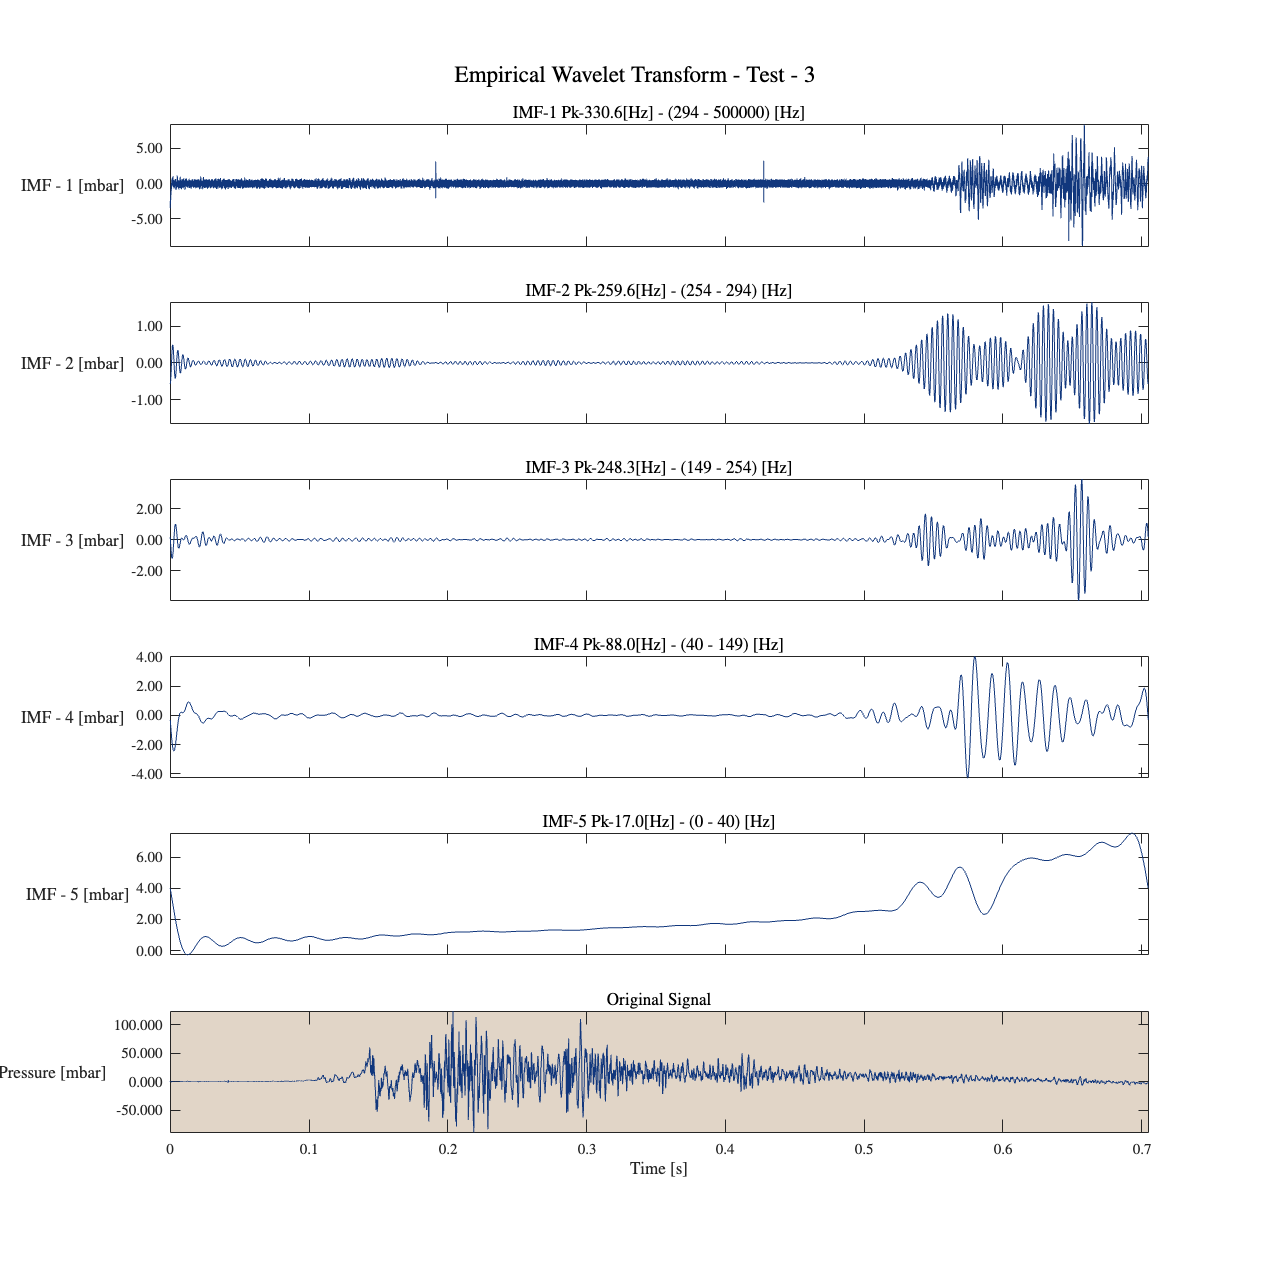


test = 3;
figure
    x0=10;
    y0=10;
    width = 75;
    height = 15 * MaxNumPeaks;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
    signal = subplot(MaxNumPeaks+1,1,MaxNumPeaks+1);
    plot(t,dataPoffsetCorrected(:,test),'Color',AuxFcn_GS.LUBlue);
    ytickformat('%.3f')  
    ax = gca;
    ax.YAxis.Exponent = 0;  % Disables scientific notation
    ylimMax = max(dataPoffsetCorrected(:, test));
    ylimMin = min(dataPoffsetCorrected(:, test));
    ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])  
    % p.XTickLabel={};
    % signal = gca;
    signal.Color = AuxFcn_GS.LUCopper_Light;
    signal.YLabel.Rotation = 0;
    signal.YLabel.HorizontalAlignment = 'right';
    signal.YLabel.VerticalAlignment = 'middle';
    title('Original Signal')
    sgtitle(['Empirical Wavelet Transform - Test - ',num2str(test)])
    ylabel('Pressure [mbar]')
    xlabel('Time [s]')
    axis tight
    for k=1:MaxNumPeaks
        modes = subplot(MaxNumPeaks+1,1,k);
        plot(t,mra_ewt(:,k),'Color',AuxFcn_GS.LUBlue)
        ylabel(['IMF -  ',num2str(k), ' [mbar]'])
        ytickformat('%.2f')  
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation 
        % ytickformat('auto')
        ylimMax = max(mra_ewt(:,k));
        ylimMin = min(mra_ewt(:,k));
        ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])  
        modes.YLabel.Rotation = 0;
        modes.YLabel.HorizontalAlignment = 'right';
        modes.YLabel.VerticalAlignment = 'middle';
        % ylabel('Pressure [mbar]')
        % title(sprintf("EWT - IMF %d", k))
        title(['IMF-' num2str(k) ' Pk-' num2str(PeakFrequencies(k), '%.1f') '[Hz]' ' - ' ' (' num2str(freqPassbands(k,1), '%.0f') ' - ' num2str(freqPassbands(k,2), '%.0f') ') [Hz]'])
        axis tight
        % s.XTickLabel={};
        set(gca,'xticklabel',[])
    end

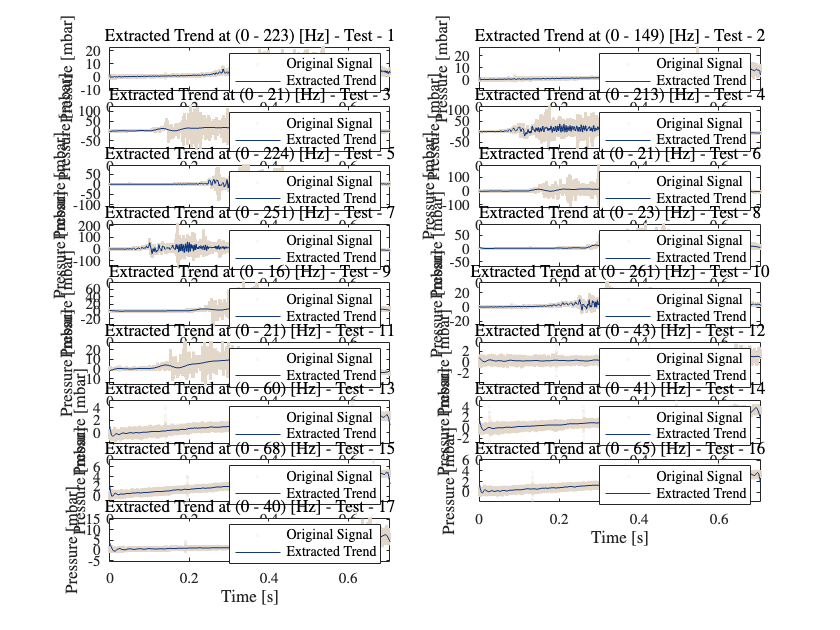


figure
for i = 1:testNum
     trend = subplot(9,2,i);
     scatter(t, dataPoffsetCorrected(:,i), '.', ...
        'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
        'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
        hold on
        plot(t, results(i).SignalRecon, 'Color',AuxFcn_GS.LUBlue); title('Band-Pass Filtered'); 
        xlabel('Time [s]'); ylabel('Pressure [mbar]');
            title(['Extracted Trend at' ' (' num2str(results(i).Passbands(MaxNumPeaks,1), '%.0f') ' - ' num2str(results(i).Passbands(MaxNumPeaks,2), '%.0f') ') [Hz]' ' - Test - ' num2str(i)])
        box on
        legend('Original Signal', 'Extracted Trend')
        axis tight
end

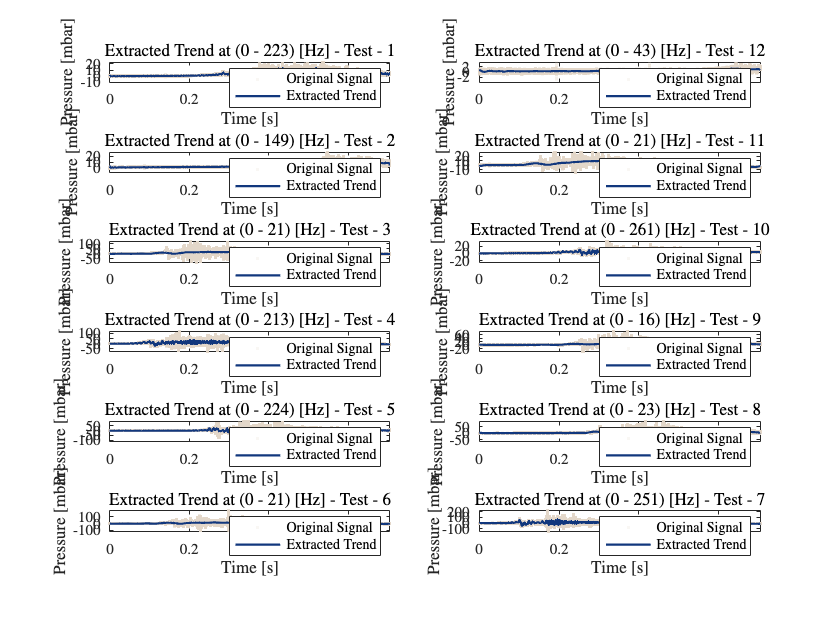

figure
rows = 6;
cols = 2;
test_pairs = [1, 12; 2, 11; 3, 10; 4, 9; 5, 8; 6, 7]; % Define pair arrangement

for i = 1:size(test_pairs,1) % Loop over rows
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);  % 20% opacity
        hold on
        plot(t, results(test_index).SignalRecon, 'Color', AuxFcn_GS.LUBlue,'LineWidth',1.5);
        title(['Extracted Trend at (' num2str(results(test_index).Passbands(MaxNumPeaks,1), '%.0f') ...
               ' - ' num2str(results(test_index).Passbands(MaxNumPeaks,2), '%.0f') ') [Hz]' ...
               ' - Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        box on
        legend('Original Signal', 'Extracted Trend');
        axis tight
    end
end

    % Convert numerical array to table format
    summaryTable = array2table(summaryData, 'VariableNames', ...
        {'Test Number', 'Mode Number', 'Peak Frequency (Hz)', 'Passband Start (Hz)', 'Passband End (Hz)'});
    
    % Display table in MATLAB
    disp(summaryTable);

    Test Number    Mode Number    Peak Frequency (Hz)    Passband Start (Hz)    Passband End (Hz)
    ___________    ___________    ___________________    ___________________    _________________

         1              1               324.89                 299.35                 5e+05      
         1              2               273.82                 268.14                299.35      
         1              3               261.05                 252.53                268.14      
         1              4               244.02                 222.74                252.53      
         1              5               201.46                      0                222.74      
         2              1                583.1                 429.88                 5e+05      
         2              2               314.9

    % Save results in the workspace
    assignin('base', 'EWT_Results', results);
    assignin('base', 'EWT_SummaryTable', summaryTable);
    fprintf('EWT analysis completed for selected tests.\n');

EWT analysis completed for selected tests.


## Selected Data for Analysis

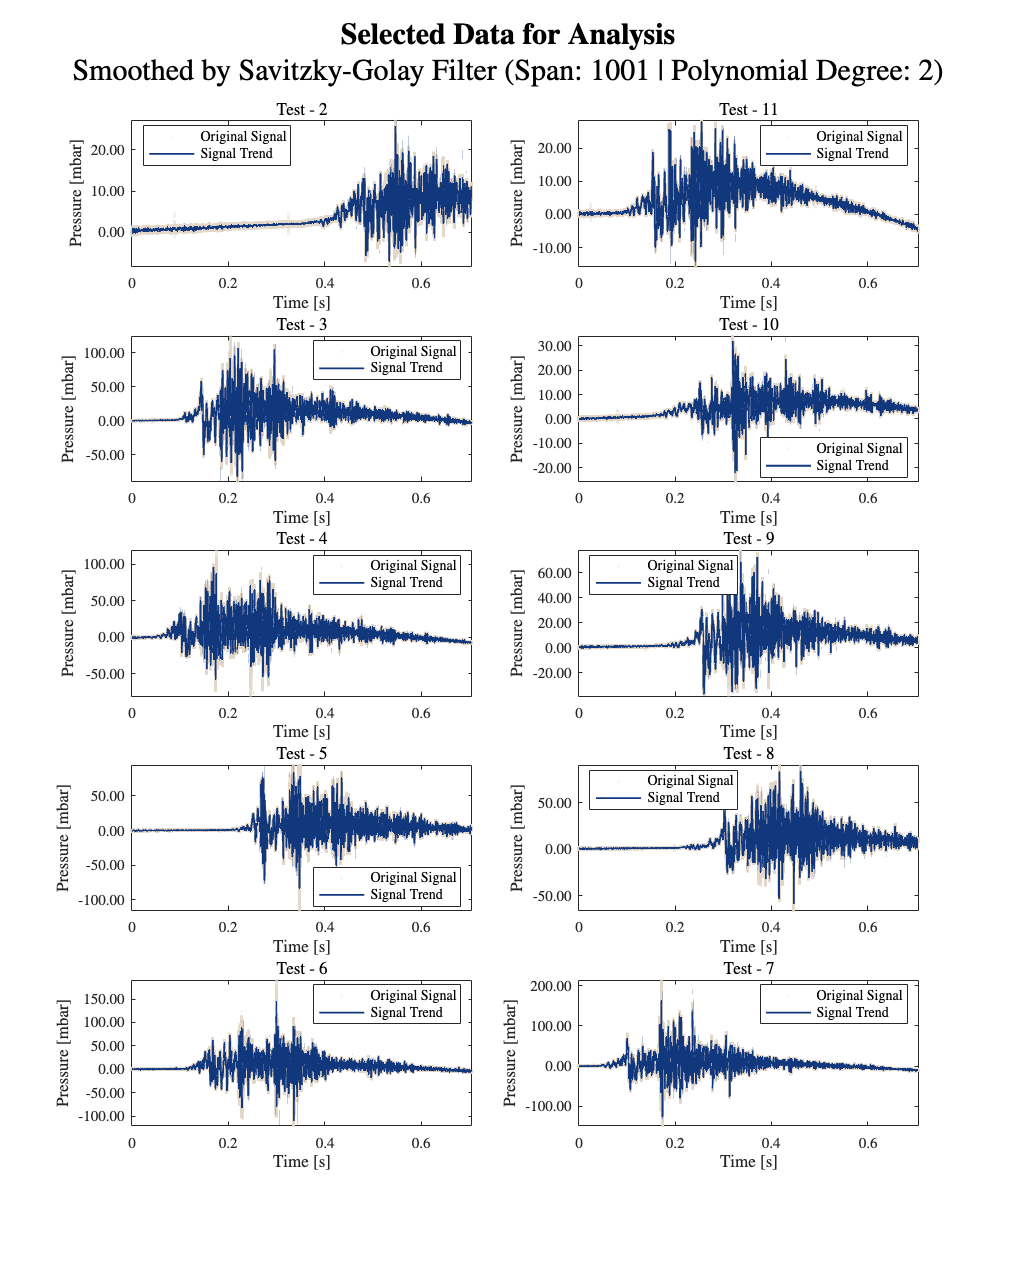

% Define number of tests based on available columns
test_numbers = [2,3,4,5,6,7,8,9,10,11];

% Define test pairs for subplot arrangement
test_pairs = [2, 11; 3, 10; 4, 9; 5, 8; 6, 7];  
rows = size(test_pairs,1);
cols = 2;

figure;
    x0=10;
    y0=10;
    width = 100;
    height = 25 * rows ;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        span = 1001;
        polyOrder = 2;
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), span, 'sgolay', polyOrder);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.2f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Title and labels
        % title(['Extracted Signal Trend - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        ylim([min(dataPoffsetCorrected(:, test_index)) + 0.2*min(dataPoffsetCorrected(:, test_index)) max(dataPoffsetCorrected(:, test_index)) + 0.2*max(dataPoffsetCorrected(:, test_index))])
        box on;
        legend('Original Signal', 'Signal Trend', 'Location', 'best');
        axis tight
        % s.XTickLabel={};
        % set(gca,'xticklabel',[])
        sgtitle({'\textbf{Selected Data for Analysis}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)
       
    end

end

hold off

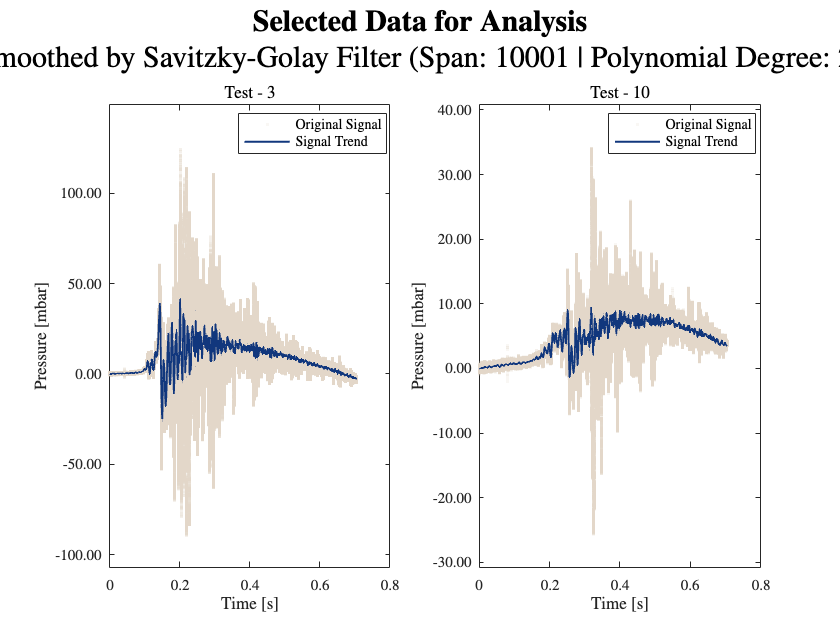

% Define number of tests based on available columns
test_numbers = [2,3,4,5,6,7,8,9,10,11];

% Define test pairs for subplot arrangement
test_pairs = [3, 10];  
rows = size(test_pairs,1);
cols = 2;

figure;
    % x0=10;
    % y0=10;
    % width = 100;
    % height = 25 * rows ;
    % set(gcf,'units','centimeters','position',[x0,y0,width,height])
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        span = 10001;
        polyOrder = 2;
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), span, 'sgolay', polyOrder);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.2f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Title and labels
        % title(['Extracted Signal Trend - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        ylim([min(dataPoffsetCorrected(:, test_index)) + 0.2*min(dataPoffsetCorrected(:, test_index)) max(dataPoffsetCorrected(:, test_index)) + 0.2*max(dataPoffsetCorrected(:, test_index))])
        box on;
        legend('Original Signal', 'Signal Trend', 'Location', 'best');
        % axis tight
        % s.XTickLabel={};
        % set(gca,'xticklabel',[])
        sgtitle({'\textbf{Selected Data for Analysis}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)
       
    end

end

hold off

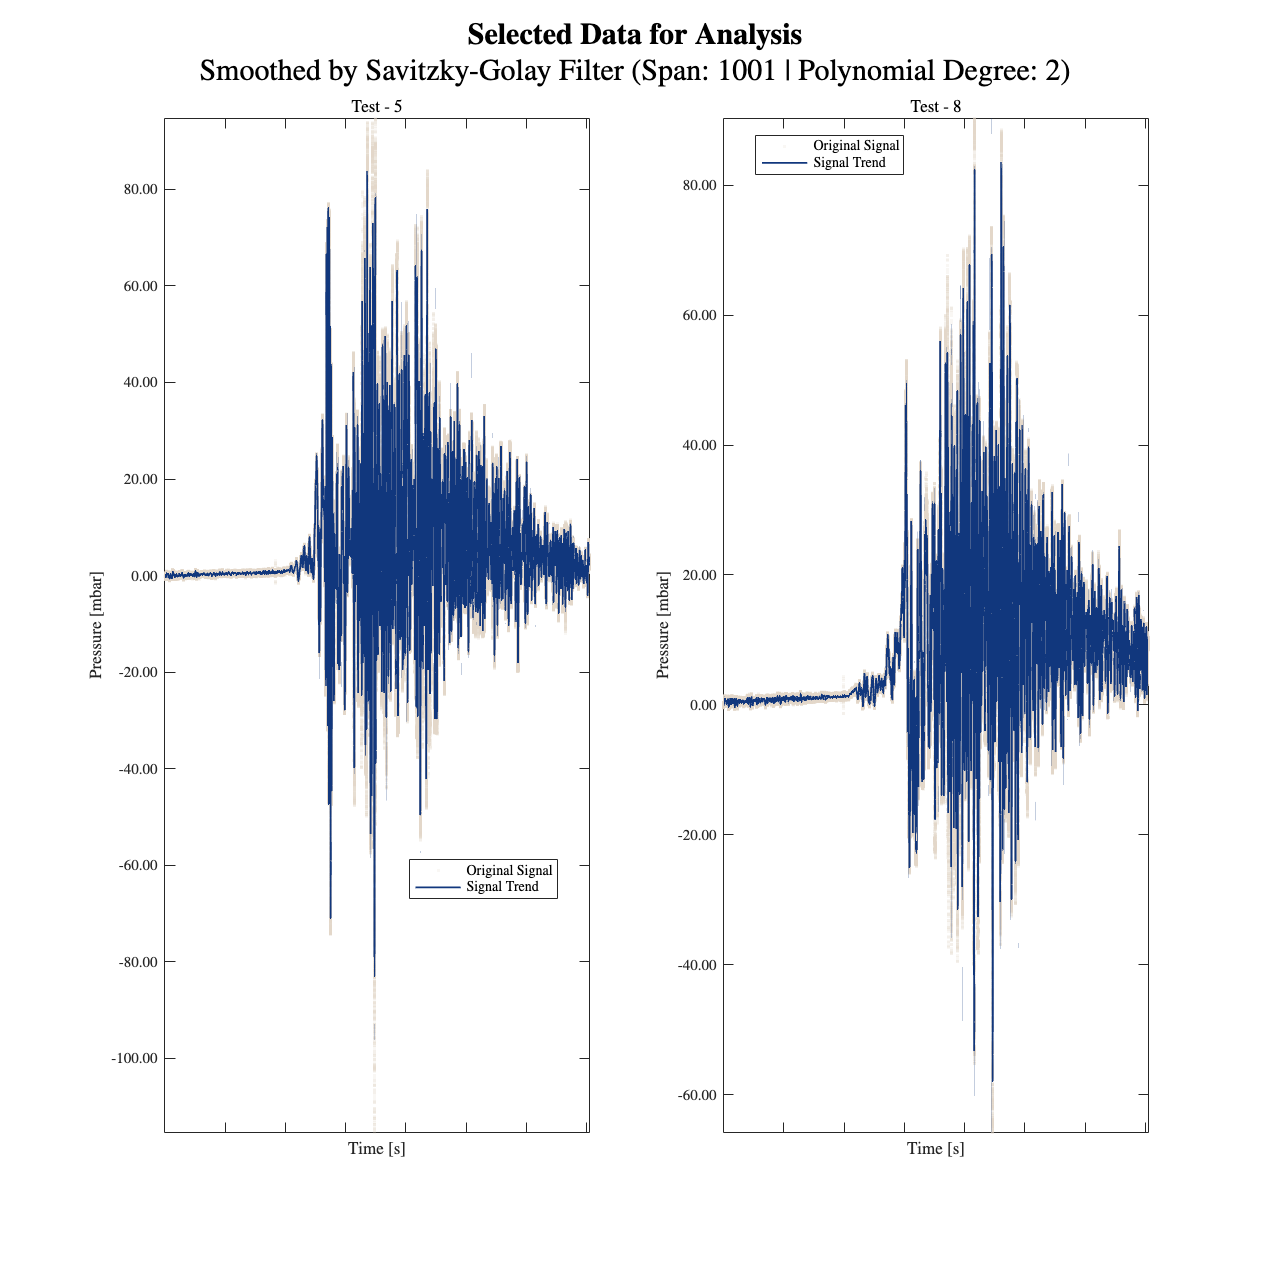

figure;
    x0=10;
    y0=10;
    width = 100;
    height = 50 * 2 ;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
        subplot(1, 2, 1); % Arrange subplots
        span = 1001;
        polyOrder = 2;
        test_index = 5;
        % Smooth the pressure signal
        smoothed_pressure(:,2) = smooth(dataPoffsetCorrected(:,test_index), span, 'sgolay', polyOrder);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.2f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Title and labels
        % title(['Extracted Signal Trend - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        box on;
        legend('Original Signal', 'Signal Trend', 'Location', 'best');
        axis tight
        % s.XTickLabel={};
        set(gca,'xticklabel',[])
        sgtitle({'\textbf{Selected Data for Analysis}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)

        hold on 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        subplot(1, 2, 2); % Arrange subplots
        span = 1001;
        polyOrder = 2;
        test_index = 8;
        % Smooth the pressure signal
        smoothed_pressure(:,11) = smooth(dataPoffsetCorrected(:,test_index), span, 'sgolay', polyOrder);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.2f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Title and labels
        % title(['Extracted Signal Trend - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        box on;
        legend('Original Signal', 'Signal Trend', 'Location', 'best');
        axis tight
        % s.XTickLabel={};
        set(gca,'xticklabel',[])
        sgtitle({'\textbf{Selected Data for Analysis}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)

hold off

## Rejected Data 

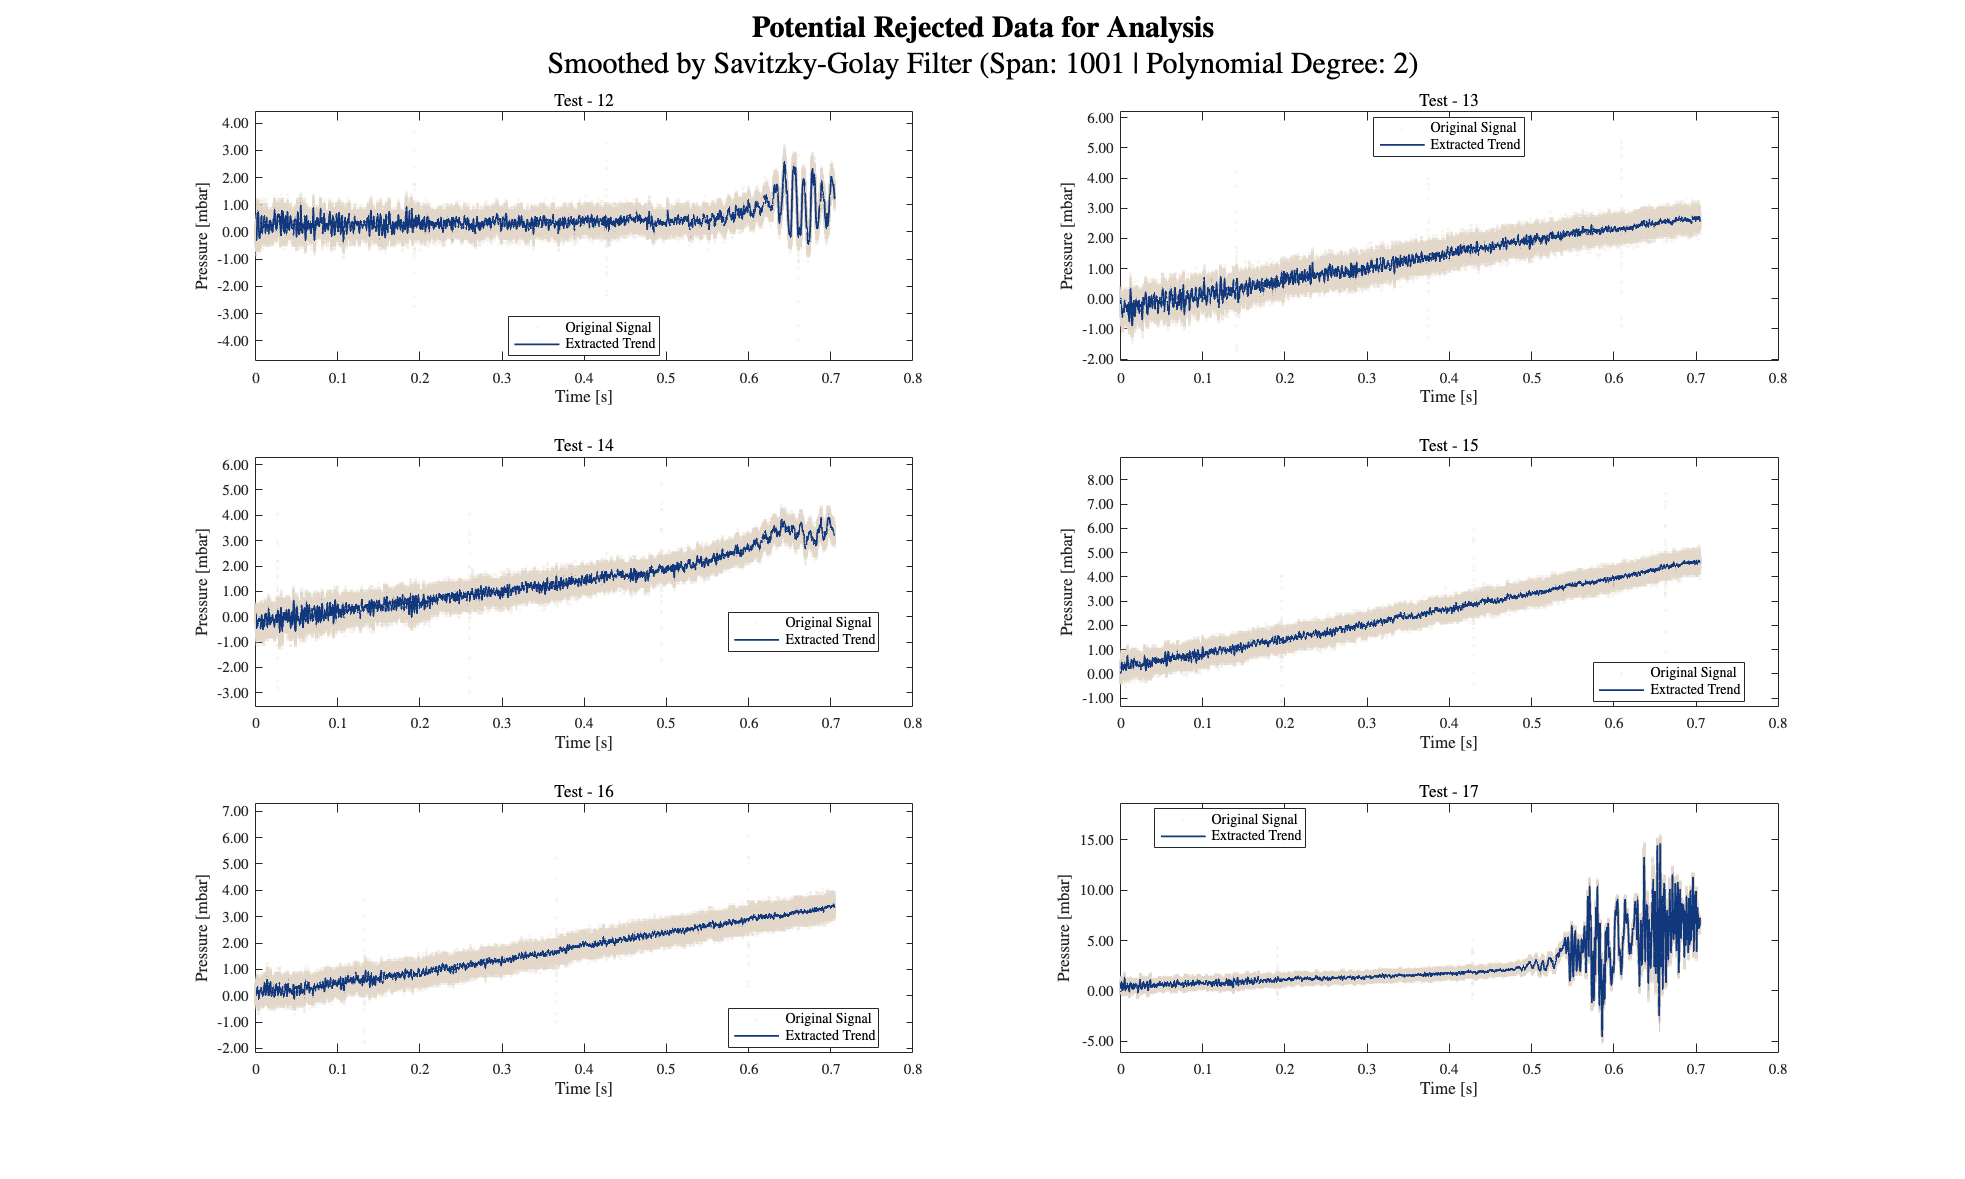

% Define number of tests based on available columns
test_numbers = [12, 13, 14, 15, 16, 17];

% Define test pairs for subplot arrangement
test_pairs = [12, 13; 14, 15; 16, 17];  
rows = size(test_pairs,1);
cols = 2;

figure;
    x0=10;
    y0=10;
    width = 75;
    height = 15 * rows ;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        span = 1001;
        polyOrder = 2;
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), span, 'sgolay', polyOrder);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.2f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Title and labels
        % title(['Ignition Time Detection - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        ylim([min(dataPoffsetCorrected(:, test_index)) + 0.2*min(dataPoffsetCorrected(:, test_index)) max(dataPoffsetCorrected(:, test_index)) + 0.2*max(dataPoffsetCorrected(:, test_index))])
        box on;
        legend('Original Signal', 'Extracted Trend', 'Location', 'best');
        % axis tight;
        % sgtitle({'Rejected Data','(Smoothed by Savitzky-Golay Filter)'})
        sgtitle({'\textbf{Potential Rejected Data for Analysis}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)
        % sgtitle({'\textbf{Example of Data Analysis}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)
    end
end
hold off

Plot the magnitude spectrum of the signal, and the filter bank. The locations of the peaks determine the filter passbands.

% figure
% f = 0:Fs/length(data):Fs-1/length(data);
% plot(f,wfb)
% ylabel('Magnitude')
% grid on
% yyaxis right
% plot(f,abs(fft(data)),'k--','linewidth',1.5)
% ylabel('Magnitude')
% xlabel('Hz')

Verify that summing the MRA components results in perfect reconstruction of the signal.

% resid_mra_ewt = max(abs(data-sum(mra_ewt,2)))

Verify energy preservation of the EWT analysis coefficients.

% cfsenergy = sum(sum(abs(cfs).^2));
% [cfsenergy norm(data,2)^2]